**Assignment 1:**

(a) In order to start of the design process, let us choose values for the lower and higher corner frequencies of our passband - we'll use an approach similar to that shown in the diagram below: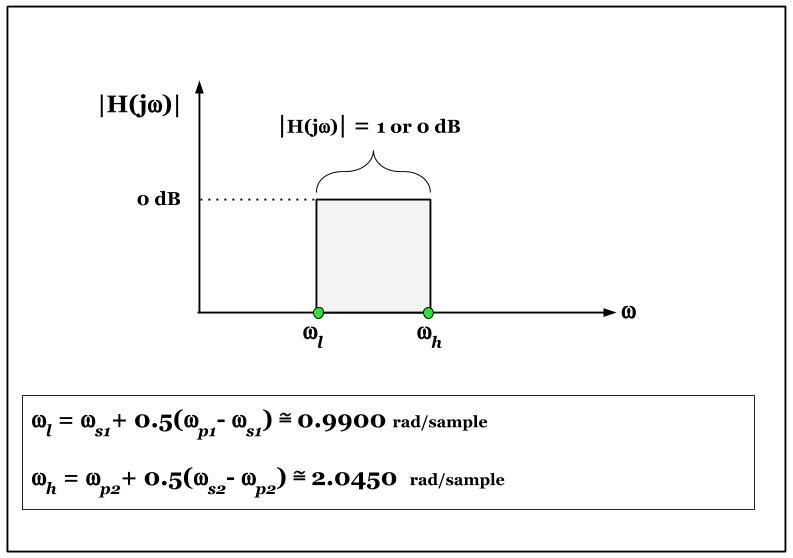

Now let's implement it in code:

ws1 = 0.77; % The lower stopband frequency in rads/s
wp1 = 1.21; % The lower passband edge frequency, again, in rads/s...
wp2 = 1.62; % The upper passband frequency...
ws2 = 2.47; % And finally the upper stopband one...

% Now, let's come up with frequency values which would
% mark the extremes of an ideal bandpass filter largely meeting
% the above criteria:

w_l = ws1 + (wp1-ws1)*0.5; % 'w_l'standing for the frequency of the
% lower corner of the bandpass characteristic...
%% This was my stupid error!
w_h = wp2 + (ws2-wp2)*0.2; % And the higher value, relating to the top corner...

**Implementing the Bilinear Transformation:**

(b) In order to try and see a pattern for generalising the implementation of the bilinear transformation, let's consider a third-order Butterworth filter:

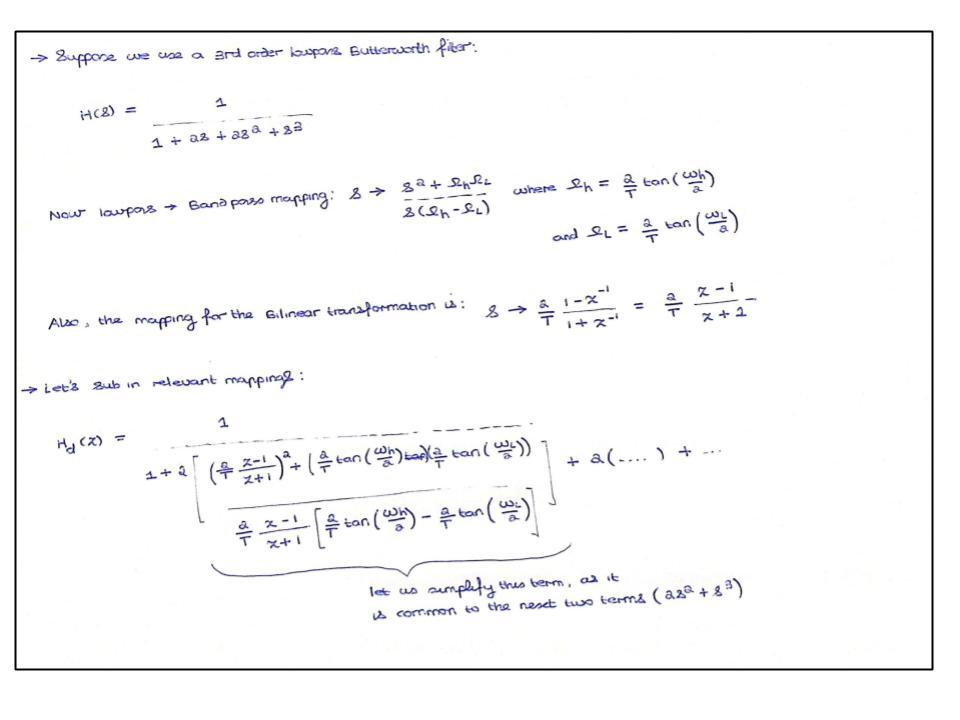

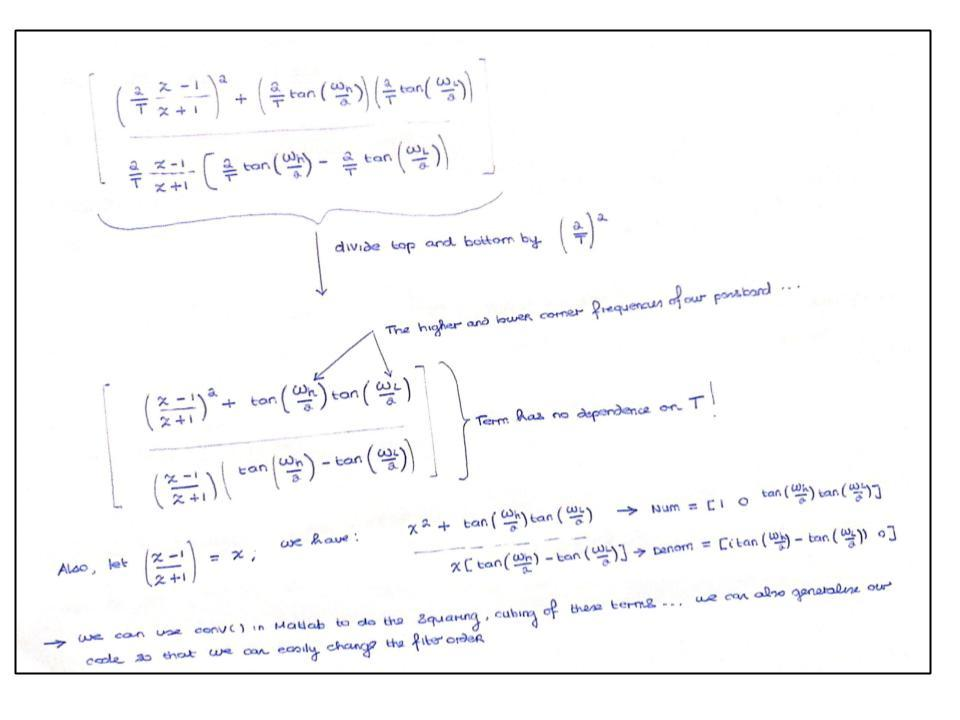

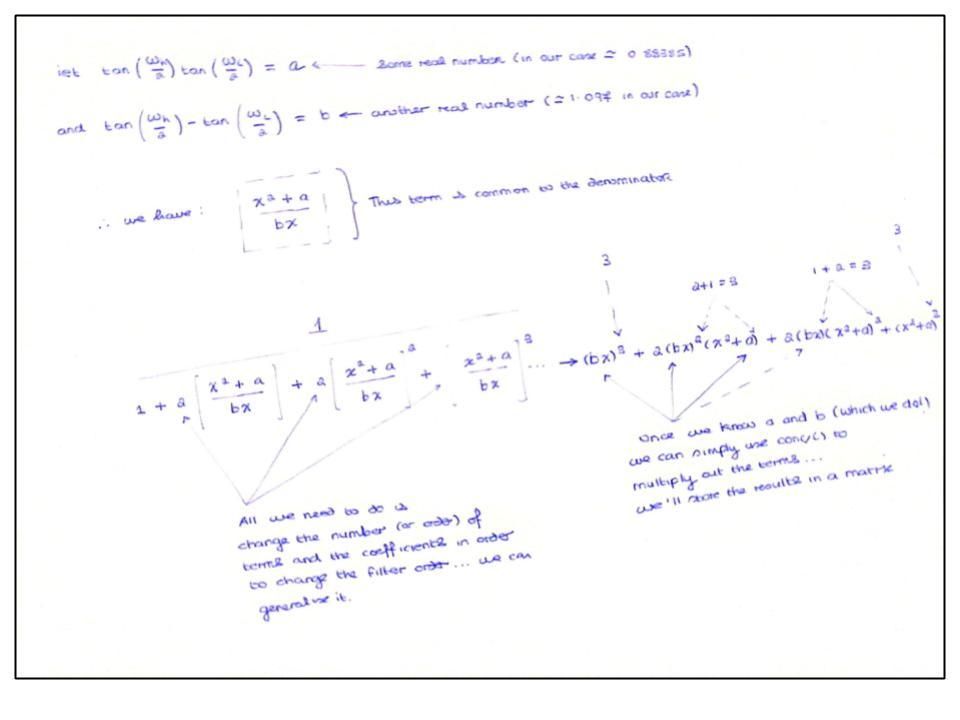

Now let's try and implement the above ideas in code:

% Next we'll let the user specify the order of the lowpass filter being
% used... the higher the number, the better the roll-off rate for the
% Butterworth filter... the charactertistic will improve...
Order = 3;

Numerator_Terms = zeros(Order+1, 2*Order+1); % This is where I'm going to store
% Numerator polynomial terms that result from using the conv( ) function...
% its size is, of course, dependent on the order of the filter chosen...

Denom_Terms = zeros(Order+1, 2*Order+1); % This matrix is similar to the above, but it
% stores the denominator terms instead... its dependence on the filter order
% number is also slightly different... I hope this is clear from the workings
% from earlier on...

Basic_Num = [zeros(1, 2*Order+1-3) 1 0 tan(w_l/2)*tan(w_h/2)]; % Our basic numerator term... as mentioned earlier
Basic_Denom = [zeros(1, 2*Order+1-2) tan(w_h/2)-tan(w_l/2) 0]; % ...and our basic denominator one...

Numerator_Terms(1, 2*Order+1) = 1; % Quite nicely, this is the case for any order Butterworth...
Denom_Terms(1, 2*Order+1) = 1; % Again, this will be the case irrespective of the filter order...

% Now we'll fill in the rest of those two matrices that we created a few lines ago:
for row = 2:Order+1 % We're starting from row 2 as the first row is already filled in...
    Numerator_Terms(row, :) = selectPart(Numerator_Terms(row-1, :), Basic_Num) % We're are performing
    % the convolution in the above line... within 'selectPart'... see the
    % function definition that I made at the very end...
    Denom_Terms(row, :) = selectPart(Denom_Terms(row-1, :), Basic_Denom)
end

Numerator_Terms =          0         0         0         0         0         0    1.0000
         0         0         0         0    1.0000         0    0.6733
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0


Denom_Terms =          0         0         0         0         0         0    1.0000
         0         0         0         0         0    0.7075         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0


Numerator_Terms =          0         0         0         0         0         0    1.0000
         0         0         0         0    1.0000         0    0.6733
         0         0    1.0000         0    1.3467         0    0.4534
         0         0         0         0         0         0         0


Denom_Terms =          0         0         0         0         0         0    1.0000
         0         0         0         0         0    0.7075         0
         0         0         0         0    0.5005         0         0
         0         0         0         0         0         0         0


Numerator_Terms =          0         0         0         0         0         0    1.0000
         0         0         0         0    1.0000         0    0.6733
         0         0    1.0000         0    1.3467         0    0.4534
    1.0000         0    2.0200         0    1.3601         0    0.3053


Denom_Terms =          0         0         0         0         0         0    1.0000
         0         0         0         0         0    0.7075         0
         0         0         0         0    0.5005         0         0
         0         0         0    0.3541         0         0         0



Denom_Terms = flipud(Denom_Terms) % Inverting the order ... it merely makes implementing the algorithm easier...

Denom_Terms =          0         0         0    0.3541         0         0         0
         0         0         0         0    0.5005         0         0
         0         0         0         0         0    0.7075         0
         0         0         0         0         0         0    1.0000



Storage_Matrix = zeros(Order+1, 2*Order+1) % Now we'll multiply the polynomials out

Storage_Matrix =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


% as I indicated above on paper...
for row = 1:Order+1
    Storage_Matrix(row, :) = selectPart(Numerator_Terms(row, :), Denom_Terms(row, :));
end

% Here we'll declare the coefficients for different order Butterworth
% filters... the user can add their own, maybe for a fifth or sixth one if
% they want...
Second_Order = [1 1.4142 1]; % Coefficients for the 2nd-order Butterworth
Third_Order = [1 2 2 1]; % ... and for the 3rd-order one...
Fourth_Order = [1 2.6130 3.4140 2.6130 1]; % ... and the 4th-order one...
Tenth_Order = [1 6.392 20.432 42.802 64.882 74.233 64.882 42.802 20.432 6.392 1]

Tenth_Order =     1.0000    6.3920   20.4320   42.8020   64.8820   74.2330   64.8820   42.8020   20.4320    6.3920    1.0000


if Order == 2
    Storage_Matrix = Storage_Matrix.*Second_Order';
end

if Order == 3
    Storage_Matrix = Storage_Matrix.*Third_Order';
end

if Order == 4
    Storage_Matrix = Storage_Matrix.*Fourth_Order';
end

if Order == 10
    Storage_Matrix = Storage_Matrix.*Tenth_Order';
end

Resultant_Denom = sum(Storage_Matrix) % Grouping all the 'like' terms on the denominator together

Resultant_Denom =     1.0000    1.4149    3.0210    2.2595    2.0341    0.6415    0.3053


% in order to get the 'Resultant' denominator...

Z_num = [zeros(1, 2*Order+1-2) 1 -1] % The numerator (z-1) expressed as vector of the needed size...

Z_num =      0     0     0     0     0     1    -1


Z_denom = [zeros(1, 2*Order+1-2) 1 1] % The denominator (z+1), again, expressed in the desired size...

Z_denom =      0     0     0     0     0     1     1



Z_num_Matrix = zeros(2*Order+1, 2*Order+1) % We'll store convolution results in these matrices...

Z_num_Matrix =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


Z_denom_Matrix = zeros(2*Order+1, 2*Order+1)

Z_denom_Matrix =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0



Z_num_Matrix(1, 2*Order+1) = 1; % Like before, we manually fill in the first row of each of these matrices...
Z_denom_Matrix(1, 2*Order+1) = 1;

for row = 2:2*Order+1
    Z_num_Matrix(row, :) = selectPart(Z_num_Matrix(row-1, :), Z_num);
    Z_denom_Matrix(row, :) = selectPart(Z_denom_Matrix(row-1, :), Z_denom);
end

Z_denom_Matrix = flipud(Z_denom_Matrix); % We reverse the order of the rows... it makes it easier to implement our idea!

Storage_Matrix2 = zeros(2*Order+1, 2*Order+1) % A second storage matrix needed for multiply terms such as (z-1)(z+1)^5...

Storage_Matrix2 =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0



for row = 1:2*Order+1
    Storage_Matrix2(row, :) = selectPart(Z_num_Matrix(row, :), Z_denom_Matrix(row, :));
end

% Finally, let us compute the numerator of our transfer function...
if Order == 2
    Resultant_Num = sum(Denom_Terms(Order+1-2, :)).*Storage_Matrix2(Order+1, :);  
end

if Order == 3
    Resultant_Num = sum(Denom_Terms(Order+1-3, :)).*Storage_Matrix2(Order+1, :);  
end

if Order == 4
    Resultant_Num = sum(Denom_Terms(Order+1-4, :)).*Storage_Matrix2(Order+1, :);  
end

if Order == 10
    Resultant_Num = sum(Denom_Terms(Order+1-10, :)).*Storage_Matrix2(Order+1, :);  
end

Resultant_Denom = flip(Resultant_Denom) % Reversing the order of the elements for implementation purposes...

Resultant_Denom =     0.3053    0.6415    2.0341    2.2595    3.0210    1.4149    1.0000


Storage_Matrix2 = Storage_Matrix2.*Resultant_Denom';
Resultant_Denom2 = sum(Storage_Matrix2); % We are essentially adding all the 'like' terms together...

**The Amplitude Response:**

Now let's see the fruits of our labour by plotting the amplitude response of our filter:

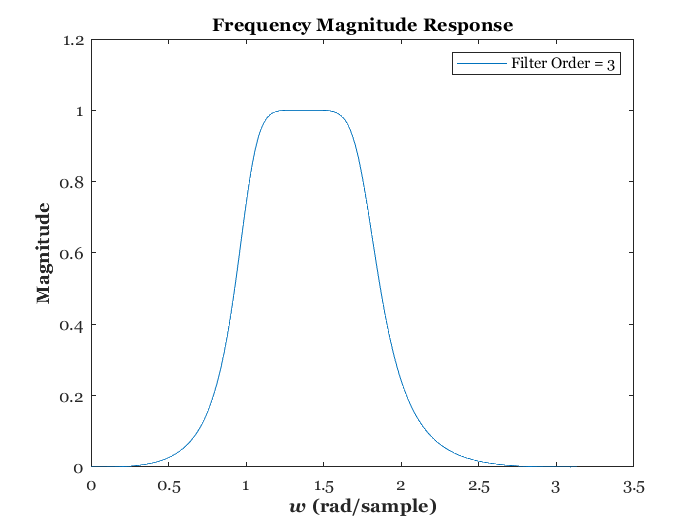

[H, w] = freqz(Resultant_Num, Resultant_Denom2);
plot(w, abs(H));
title('\bf\fontname{Georgia}Frequency Magnitude Response');
ylabel('\bf\fontname{Georgia}Magnitude');
xlabel('\bf\fontname{Georgia}\itw\rm\bf (rad/sample)');
set(gca,'Fontname', 'Georgia');

 legend_text = sprintf('Filter Order = %i', Order); % We'll also display the order of the lowpass filter we began with... 
 legend(legend_text);

As can be seen, we have a nice flat passband as well as a good 'roll-off' rate, meaning the gain drops off fairly quickly once a frequency value falls outside the passband range.

Below I've attached two graphs: one documenting a the response of a 2nd-Order Butterworth, and the other showing a 4th-Order one... it's clear that as the order increases, the characteristic becomes more in line with an ideal 'brick wall' one...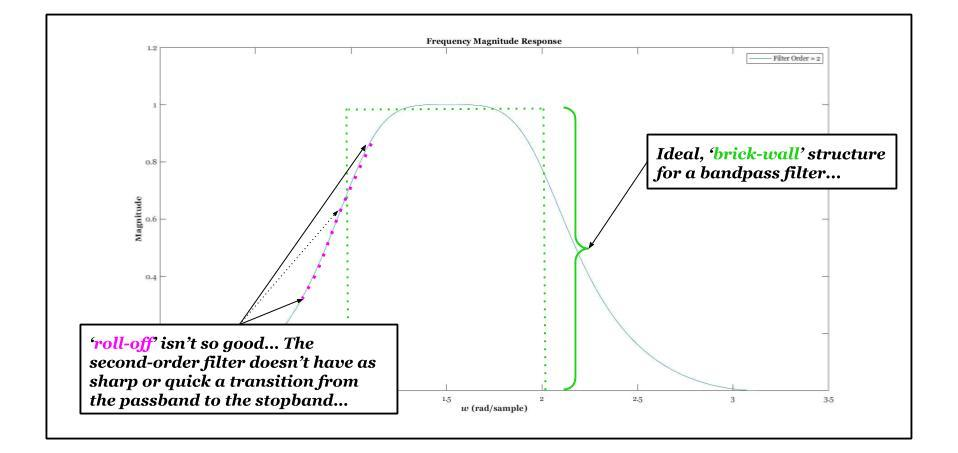

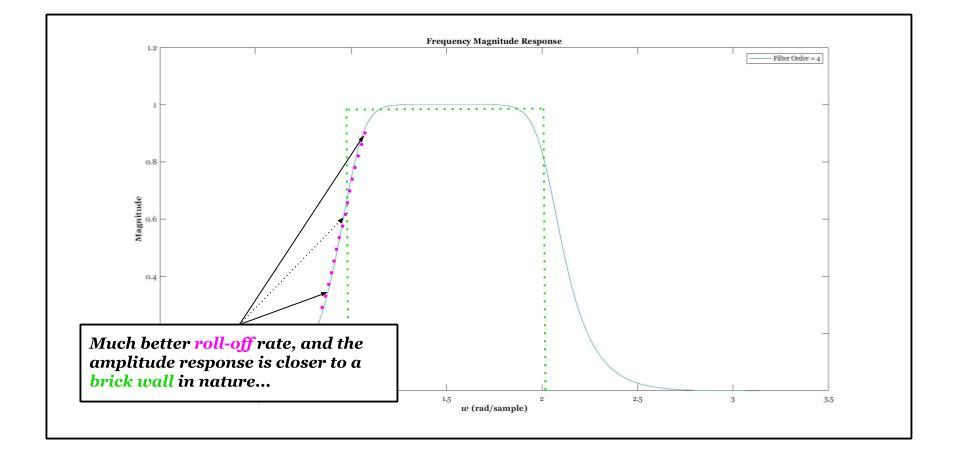

(c) Next, suppose we wanted to forfeit *some *precision in our filter coefficients but still have a sufficient amplitude response - we might try and quantize them - the basic principle is like that in a digital-to-analog converter: the analog signal may have have any value at any time, but you quantize the vertical axis and match the analog signal's value, say a voltage, to the closest level or threshold...

Most of our filter coefficients are floating-point or real numbers, not simply integers. Hence, in the binary representation there'll be 1s and 0s after the so-called 'radix' point... these are the so-called fraction bits: the bits representing the fraction part of the original decimal number.

Let's make use of the function, quantizenumeric( ). In order to make proper use of this function, we'll need to specify such things as the 'wordlength', which is the number of bits to be used to represent a given number, as well as the number of 'fractional bits', the bits to the right of the radix which represent the fraction part - if these were to be made 0, then we'd be working with integers and precision would most likely be lost!

MaxVal = max(abs([Resultant_Denom2 Resultant_Num])) % Let's work out the maximum

MaxVal = 18.0274

% value from all our filter coefficients - this will help us
% find out the least how low the we can afford to go with the wordlength...

% Now, sort of similar to the 'squeeze theorem' in calculus, we'll hone in
% on the quasi-optimal/minimal number of bits needed for the adequate
% representation of the filter's coefficients by changing the wordlength
% and number of fractional bits. This may seem 'random' or 'crude', but
% seeing as there's no analytical method to solve the problem, it may prove to be the most
% practical and time-efficient way...


Num_fractionalBits = 4; % The number of fractional bits...
quantizedArray = zeros(1, 10);
wordLength = 6; % Our starting value for the wordLength...

for i = 1:numel(quantizedArray)
    quantizedArray(i) = quantizenumeric(MaxVal, 1, wordLength, Num_fractionalBits, 'ceil');
    wordLength = wordLength + 1; % Let's increase the wordlength (i.e. the number of bits used to stored the number)
    % and see what effect it has...
end

% One can change or tweak the values and see that a wordlength of 14, in
% combination with 4 fractinal bits maintains a nice closeness to the 
% filter coefficients we calculated before...

Wl = 14;
N_Fraction_Bits = 4;

quantizedFilter_Numerator = quantizenumeric(Resultant_Num, 1, Wl, N_Fraction_Bits, 'ceil');
quantizedFilter_Denom = quantizenumeric(Resultant_Denom2, 1, Wl, N_Fraction_Bits, 'ceil');

Now let's see how the amplitude response looks:

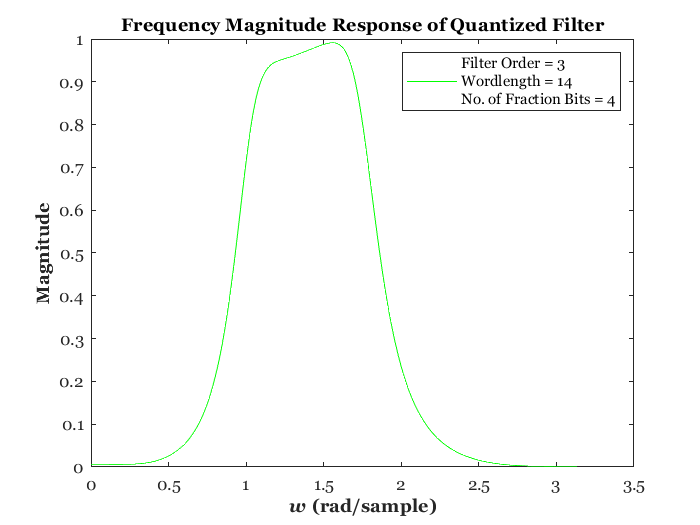

[H2, w2] = freqz(quantizedFilter_Numerator, quantizedFilter_Denom);
plot(w2, abs(H2), 'color', 'g');
title('\bf\fontname{Georgia}Frequency Magnitude Response of Quantized Filter');
ylabel('\bf\fontname{Georgia}Magnitude');
xlabel('\bf\fontname{Georgia}\itw\rm\bf (rad/sample)');
set(gca,'Fontname', 'Georgia');

legend_text = sprintf('Filter Order = %i\nWordlength = %i\nNo. of Fraction Bits = %i', Order, Wl, N_Fraction_Bits); % We'll also display the order of the lowpass filter we began with... 
legend(legend_text);

function ChosenPart = selectPart(u, v) % This function will return the part of the convolution calculation that's of interest to us...

Full_Ans = conv(u, v); % The full length convolution...
ChosenPart = Full_Ans(numel(Full_Ans)-(numel(u)-1):numel(Full_Ans)); % We're choosing the relevant part for our task...

end